# 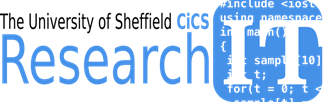                                      

# **Matlab Fundamentals**

# Introduction

### Learning Outcomes

- Manipulate data sets using Matrices, Tables, Cell Arrays and Structures

# Preliminaries

### Vectors and Matrices

Manual entry array of an array, using the [] bracket notation

- columns separated with a space

- rows separated by a ;

%x= % 1x3 row vector elements separated with spaces
x=[1 2 3]
%y=[] %2x1 matrix  column vector elements separated by ;
y=[sqrt(10); pi^2; sin(pi/4)]
%z=[]  % 2x3 matrix
z=[4 5 6; 7 8 9]

Convert row vector to column vector using transpose ' operator

xt=x'
%

Functions to define array using linspace and the colon notation

u=zeros(2,2);
v=eye(3,3);
w=ones(4,4);
x1=linspace(1,10,5);
y1=(1:1:10);
z1=rand(5,1);
 % linspace(first,last,number of elements)
 %note using transpose


Inspect the work space

 % who list of variables
 who

 % whos list showing properties
 
 whos

### Array operations

We use the [] brackets to assign elements in the array.

The () brackets are used extract elements which we demonstrate below

First create a 6x4 matrix of random numbers.

data=100*rand(6,4)

%x1= %extract  a specific element
x1=data(2,2)

Note below the use of the end keyword

%x2= %get item  at row 6  and column 2
x2=data(end,2)
x3=data(end-1,end-2)


### Extracting multiple elements

Create a row vector from the data set

x3=data(2,:)%


Create a column vector from the data set

x4=data(2:end-1,2)%

Change values in the array, first create a sub array

v1=data(:,end-1:end)
v1(1,2)=10
v1


change one element of v1

%v1();%
%v1();%
x5=v1(1:end,2)
x5r=v1(end:-1:1,2) % array in reverse

### Operations on Matrices

vr=round(10*x3)
[vmax,loc]=max(data)


Look at the behaviour of the multiply operation, we use a simple row and column vector to illustrate

row=[1 2 3]
col=[4;5;6]
row*col
col*row
col.*row
row.*col

Now try a matrix multiply, a pair of simple square matrices clearly illustrates correct matrix multiplication and the behaviour of the dot operator i.e. element wise operation

m1=[1 2; 3 4]
m2=[2 0; 0 2]

m2*m1

m2.*m1

### Multiple Output Function Calls

Multiple outputs are normally returned as a row vector (comma or space separated elements). Functions may also return data as a cell array which we will see later.

numd=numel(data)

%size of data
dsize=size(data)
%numrows, numcols
[numrows,numcols]=size(data)

%maximum and index of maximum of data
[maxd,idmax]=max(data)

A particularly useful function is the reshape function.

Example create a row vector of 16 values and reshape to a 3x4 matrix

rv=1:12
%rmat reshape rv as 3x4
rmat=reshape(rv,[3,4])

Clear the workspace and the variables

clear('u') %clear specific variable note use of quotes
clear %clear the workspace
%clear all to clear the whole workspace
%clc %clear the command window

x=round(20*rand(3,3));
y=round(20*rand(3,3));



## Relational and Logical Operations

For this esction we will use some examples from the numerical analysis folder in particular looking at  problems for finding the root of an equation using the bisection method and the newton-raphson method

Matlab represents true and false by means of the integers 0 and 1.

true = 1, false = 0

If at some point in a calculation a scalar x, say, has been assigned a value, we may make certain logical tests on it:

x == 10 %is x equal to 10?
x ~= 10 %is x not equal to 10?
x > 10 %is x greater than 10?
x < 10 %is x less than 10?
x >= 10 %is x greater than or equal to 10?
x <= 10 %is x less than or equal to 10?


Pay particular attention to the fact that the test for equality involves two equal signs ==. When x is a vector or a matrix, these tests are performed elementwise:

x=[ -2 pi 5; -1 0 1]
x==0
x>1,x>=1


We may combine logical tests, as in

x > 3 & x < 4  %logical and
x > 3 | x == -3  %logical or

As one might expect, & represents and and (not so clearly) the vertical bar | means or;  also ~ means not as in ~= (not equal), ~(x>0), etc.

%try x>3 or x==-3 or x less than or equal to -5


One of the uses of logical tests is to mask out certain elements of a matrix.

## Find function

Find returns the indices of the vector that are non-zero. When used with relational operators it will return the indices of a vector satisfying a given condition.

%TODO use find function to return indices for which x values are greater than or equal to pi  

 x
 indpi=find(x>=pi)
 x(3)
 x(5)

Results of the find() function can be used as an index vector to select or eliminate data which meets a certain criteria. 

       a = [ 1.3 5.6  7.8  2.0  4.0 3.8   2.5]
     % create k find values of a<3 (k contains indices)
  %     %create a new vector c made up of the kth  elements of a in that order. 
k=find(a>3)
anew=a
anew(k)=3
anew

# Programming Constructs

## Program Control Using Loop Control and Conditional Statements

There are occasions that we want to repeat a segment of code a number of different times (such occasions are less frequent than other programming languages because of the : notation).

mysum1=0.0
mysum2=0;
for v=1:5
   mysum1=mysum1+v
   mysum2=mysum2+(1/v);
end


For the above loop the commands between the lines starting `for `and `end` are repeated with v being given the value 1 the first time through, 2 the second time, and so forth, until v = 5. The interval can easily be changed using the colon notation.

%using a function and changing the interval
mysum2=0.0
for v=1:2:11
   mysum2=mysum2+sin(v/(2*pi)) ;
end

%pause;

mysum3=0;
w=[1 2 5 7 8 9 11 ];
for v = w
   mysum3=mysum3+v ;
end

mysum4=0;
A=rand(4,3)  %each column of the matrix will be passed in turn
for v = A
   mysum4=mysum4+v 
end


#### if...then...else...end

This allows us to execute different commands depending on the truth or falsity of some logical tests. To test whether or not e is greater than, or equal to, e:

a = pi^exp(1), c = exp(pi), a^c, c^a
%TODO set correct b value if a>=c to sqrt(a^2-c)
if a>=c
    b=sqrt(a^2-c^2)
end

so that b is assigned a value only if a >= c. A more common situation is

if a >= c
    b = sqrt(a^2 - c^2)
else
    b=0
end

which ensures that b is always assigned a value and confirming that a < c. A more extended form is

if a >= c
    b = sqrt(a^2 - c^2)
elseif a^c > c^a
    b = c^a/a^c
else
    b = a^c/c^a
end

The general for m for the if.. else if structure is

% if logical test 1
%     Commands to be executed if test 1 is true
% elseif logical test 2
%     Commands to be executed if test 2 is true but test 1 is false
%     ...
% end

#### While Loop

There are some occasions when we want to repeat a section of Matlab code until some logical condition is satisfied, but we cannot tell in advance how many times we have to go around the loop. This we can do with a while...end construct.

Example: What is the greatest value of n that can be used in the sum

1^2 + 2^2 +..... � +(n-2)+ (n-1)^2 + n^2

and get a value of less than 100?

S = 1; n = 1;
while S+ (n+1)^2 < 200
    n = n+1; S = S + n^2;
end
[n, S]

The root finder using the bisection method is an excellent illustration of usage of the while loop

%addpath('../matlab_examples/numericalanalysis/root_bisection/')
%edit root_bisection; %inspect the script


root_bisection;



clear all;
addpath('../matlab_examples/numericalanalysis/root_newton')
edit root_newton

root_newton;

# Using Functions and Scripts

Function files are a combination of the ideas of script  and mathematical functions.

1. Decide on a name for the function, making sure that it does not conflict with a name that is already used by Matlab.

2. The first line of the file must have the format:

`function [list of outputs]= function name(list of inputs)`

3. Document the function. That is, describe the purpose of the function and how it can be used. These lines should be preceded by % which signify that they are comment lines that will be ignored when the function is evaluated.

4. Finally include the code that defines the function. This should be interspersed with sufficient comments to enable another user to understand the processes involved.

Consider the differences between funcntions and scripts

- A sequence of matlab commands can be put into a file which can later be executed by invoking its name.  The files which have .mextensions are recognised by Matlab as *Matlab**Script*or *Matlab** Function*files.

- If an mfile contains the keyword **function** at the beginning of its first line it is treated as a Matlab function file.

- Functions make up the core of Matlab. Most of the Matlab commands “apart from a few built-in ones”  are in fact matlab functions. 

Use the matlab_examples numerical analysis root_newton Run the root newton example as a script

root_newton_script

Run the newton solver as a function

clear all


- Most Matlab commands are in fact functions (provided in .m files of the same name) residing in one of the Matlab path directories. See path command.

- Matlab searches for scripts and files in the current directory first and then in the Matlab path going from left to right. If more than one function/script exists with the same name, the first one to be found is used.  “***name-clash***”  

- To avoid inadvertent name-clash problems use the which command to check if a function/script exists with a name before using that name as the name of your own function/script or to find out that the function you are using is really the one you intended to use!

-      Example :  *which **mysolver*

- lookfor and what commands can also help locate Matlab functions. 

- Having located a function use the type command to list its contents.

a = 0;
b = 3;
hf= @testf;
hderivf= @testderivf;
root_newton_function(hf,hderivf, a, b);
%cd ../../../presentations/



### Differences between functions and scripts

- Matlab functions **do not**use or overwrite any of the variables in the workspace as they work on their own private workspace. 

- Any variable created within a function is not available when exited from that function. ( Exception to this rule are the Global and Persistent variables)

# Data Types

Numeric

- Complex, 

- double precision

- Single precision

- Integer 

- Boolean

- Character String

- Java Classes

- User Defined MatlabClasses

###   **ORGANIZATIONAL ATTRIBUTES**

- Multi-dimensional Matrices

- Sparse Matrices

- Cell Arrays

- Structures & Objects

### **Complex double precision matrices**

- This is the default storage mode.

- A scalar is really a 1x1 matrix with the imaginary part set to zero.

- Any expression which evaluates to a complex value returns complex results automatically

- The following are two methods of expressing a complex number;


%X = complex( 1.2 , 3.4 )
%X = 1.2+3.4i

- Warning i and j has this special meaning which will be lost if you name your variables as iand j . So don’t !

- Matlab keeps track of complex vs real issues and does the necessary conversions. Therefore you need not worry about it.

### Logical Matrices

- Results of relational operations return logical matrices ( with 1’s and 0’s only )

- These matrices are primary useful for program control structures and they can implicitly be used as masks in vectorisation

a = rand (1,10);   
b = rand(1,10); d= 1:10;
%c = a < b    % c is a logical matrix.
a(c) = [ ]   % eliminate elements where a<b 


### Character Strings

A Character string is simply a 1 by n array of characters.

name='tommy'
%TODO
%friends = [ 'tommy' ; 'billy'  ;  'tim  ' ]

 Note that all items must have the same length by padding them with blanks where necessary. This ensures that the matrix convensionis not violated. Where as; 

%TODO
% friend = [ 'Alexandra' , 'jim' ] 

is a valid construct as the resultant structure is simply an array. In this case friend(3) is ‘e’ for example. 

### Multi-dimensional Arrays

- •These are arrays with more than 2 subscripts

- •They can be generated by using one of the following functions;

 ` zeros  ,  ones  ,  rand ,  randn`

 R = zeros ( 10,20,20);
 A = ones( 10,20)
 R(:,:,1) = A
 

### Structures

These are Matlab arrays with elements accessed by field names. They are useful for organizing complex data with a known structure. Structures can be nested.

Creating a structure

 order.number= 105; order.year=2003; order.title='Smith';
 %TODO
 %order(2)= %struct( 'number',207,'year',2003, 'title','Jeff Brown') 

Deleting fields

 %TODO
 %use rmfield to remove the year field from order
% modorder = ;

### Cell Arrays

Cell arrays are Matlabarrays whose individual elements are free to contain different types & classes of data. These elements need not ‘and usually are not’ of same type, size or shape. They are useful for storing data that can not otherwise be organized as arrays or structures.  Cell arrays can be nested.

Create a 4by2 cell matrix. Each cell can contain any type and size of data

 C = cell(4,2)  
 

Create (4by1)cell array B and assign values:

 B = { [1,2] , [ 4 5 ; 5 6] , 0.956 , 'range values'} 
 D = { [1,2] , [3,4], [5,6] } 
 

Build a (1by5) cell-array M containing 5 elements,  one cell at a time:

M{1} = 1 ; M{2}= [1 2 3] ; M{3} =[1 2;3 4] ;
M{4} = rand(10,10) ; M{5}='title' ;
cell2mat(D) %elements of cell array need to be of same data type!
